# Test out some butterworth filters!

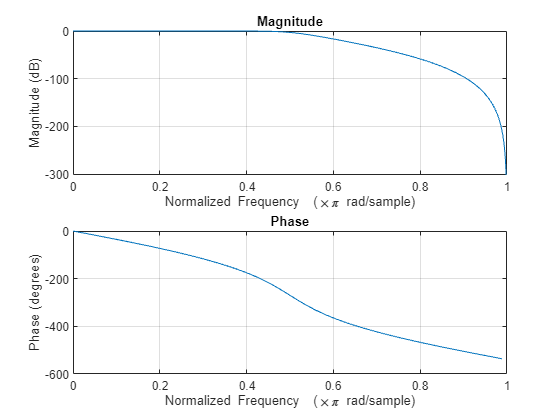

[b,a] = butter(6,0.5);

figure;
freqz(b,a)

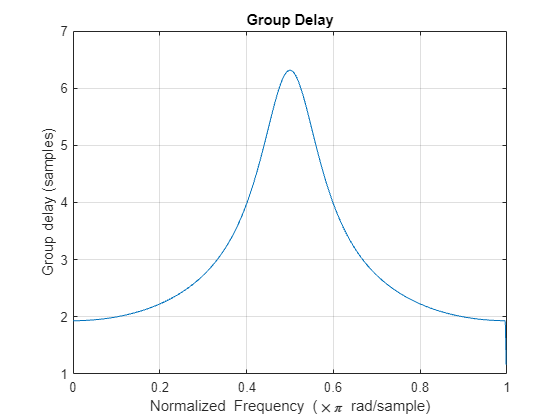


grpdelay(b,a)

## Alternate

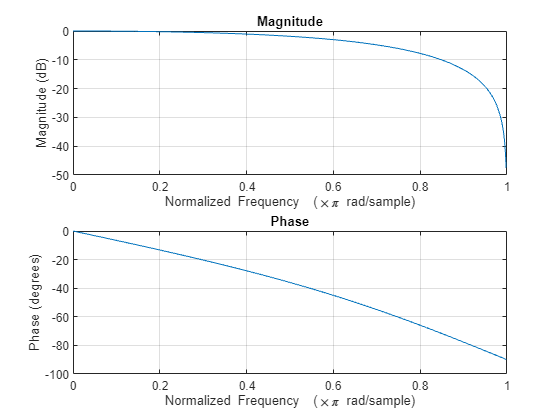

[b,a] = butter(1,0.6);

figure;
freqz(b,a)

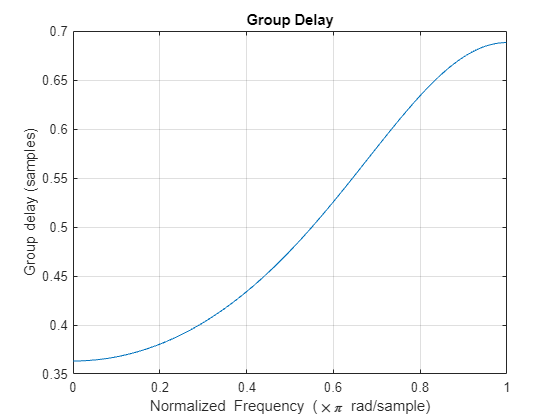


grpdelay(b,a)

## MATLAB Tutorial for Digital Filtering

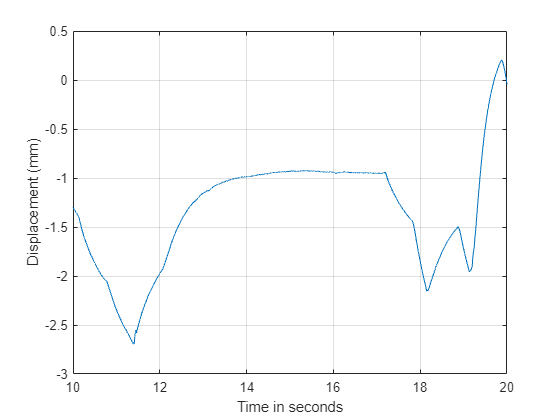

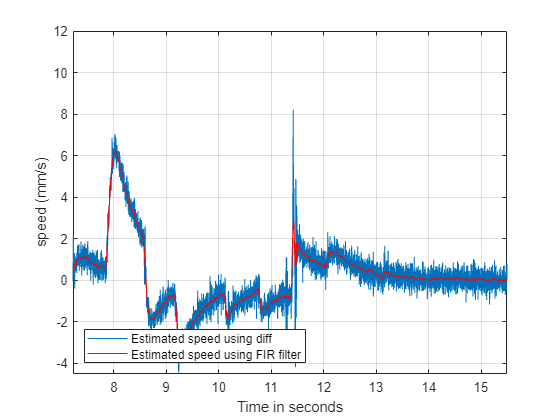

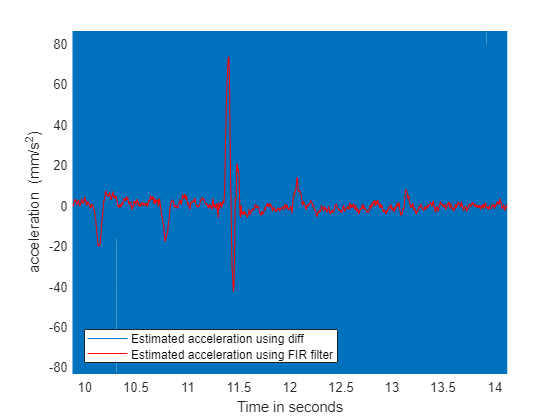

% load quakedrift.mat 
Fs  = 1000;                 % Sample rate
dt = 1/Fs;                  % Time differential
t = (0:length(x_pos)-1)*dt; % Time vector

df5 = designfilt("differentiatorfir", ...
    FilterOrder=50, ...
    PassbandFrequency=0.1, ...
    StopbandFrequency=10, ...
    SampleRate=Fs);

fvtool(df5)

% fa = filterAnalyzer(df5, ...
%     MagnitudeMode="zerophase", ...
%     FilterNames="FIR_Differentiator_50th_Order");
% addFilters(fa,[1 -1],1, ...
%     SampleRate=Fs, ...
%     FilterNames="Response_of_Diff_Function");


v1 = diff(x_pos)/dt;
a1 = diff(v1)/dt;

v1 = [0; v1];
a1 = [0; 0; a1];


D = mean(grpdelay(df5)); % Filter delay
v2 = filter(df5,[x_pos; zeros(D,1)]);
v2 = v2(D+1:end);
a2 = filter(df5,[v2; zeros(D,1)]);
a2 = a2(D+1:end);
v2 = v2/dt;
a2 = a2/dt^2;


figure;
helperFilterIntroductionPlot2(t,x_pos,v1,v2,a1,a2)